# MATLAB calling TensorFlow model for Image Classification using a Live Task

Using the MATLAB Live Editor task for Python enables users to write or copy & paste Python code into MATLAB.

Steps to use the MATLAB Live Editor task for Python are:

- Write or copy & paste Python code into the Live Editor task

- Define MATLAB input variables to be called in Python

- Define Python output variables to be called in MATLAB

## Requirements

The example requires the following to be intalled:

- [MATLAB R2024b](https://www.mathworks.com/products/matlab.html)

- [Tensorflow 2.8](https://www.tensorflow.org/install)

- [Python 3.8+](https://www.python.org/downloads/)

## Read in image

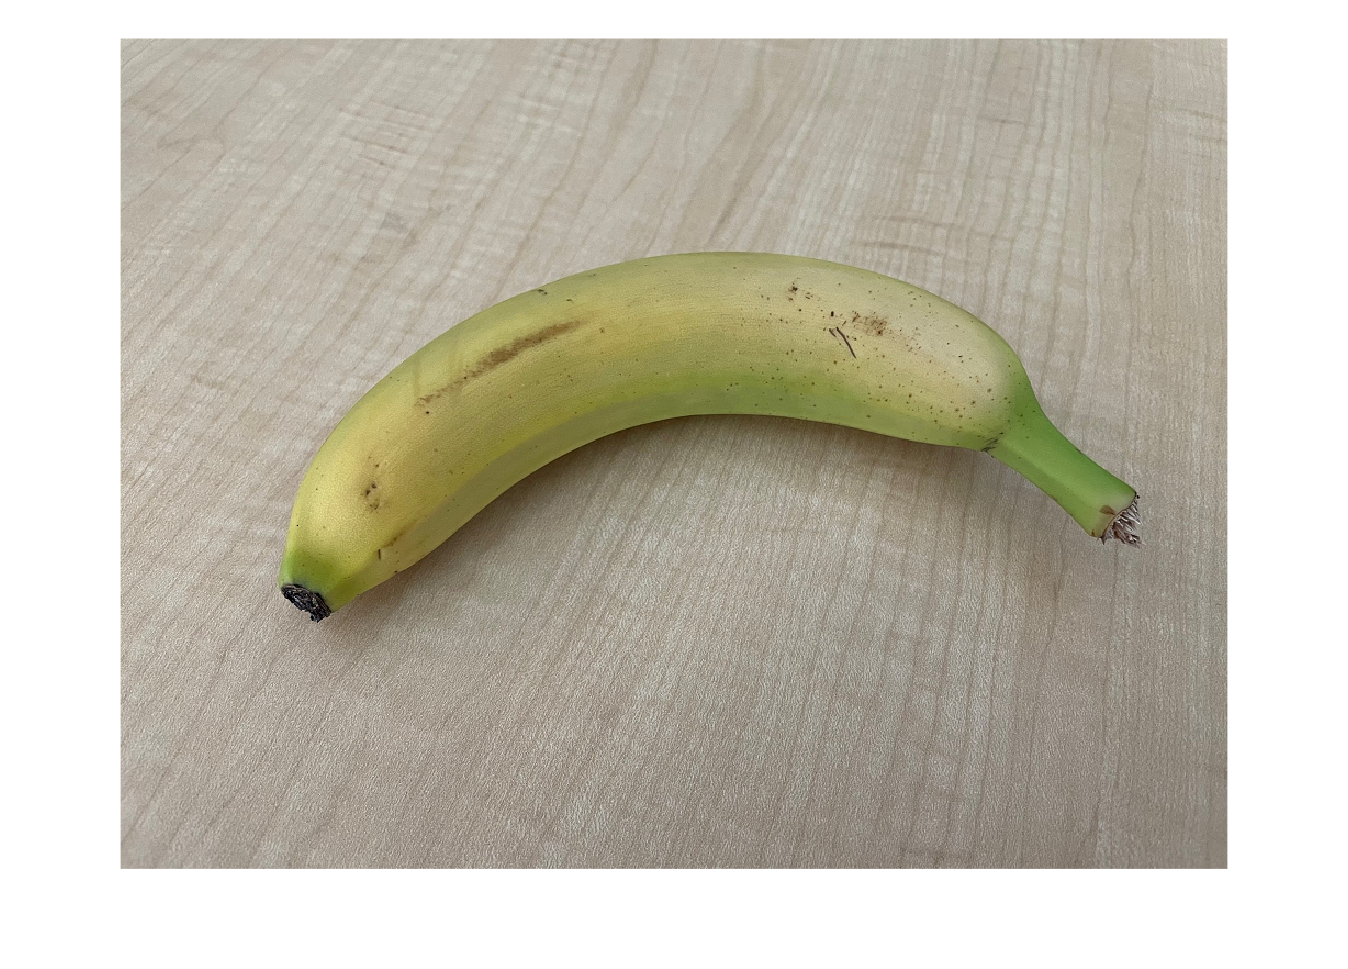

imgOriginal = imread("./Images/banana.png");
imshow(imgOriginal)

Each pretrained model in tensorflow.keras.applications takes input images of different sizes. Therefore the image being classified needs to be resized. 

imageHWSize = 480;
img = imresize(imgOriginal, [imageHWSize, imageHWSize]);

TensorFlow orients image data in a different format to MATLAB. This requires conversion (HWCN TO NHWC)

imgforTF = permute(img, [4 1 2 3]); 
batch_size = int32(1); % Tensorflow require inputs to be converted to int32.

## Classify Image via TensorFlow Coexecution

Importing EfficientNetV2L pretrained model from keras.applications

The MATLAB Live Task for Python holds the state of the Python environment between live tasks' runs whenever the code to run comes in the form of Python statements. That is, it behaves in a stateful way. 

On the contrary, if you are running a Python script file, it runs stateless.

% Python code input
pycode = [...
"from tensorflow.keras.applications import efficientnet_v2",...
"import numpy as np",...
"",...
"model = efficientnet_v2.EfficientNetV2L()",...
"X = np.asarray(imgforTF)",...
"X = efficientnet_v2.preprocess_input(X)",...
"Y = model.predict(X, batch_size)",...
"Y_decoded = efficientnet_v2.decode_predictions(Y)",...
"label = Y_decoded[0][0][1]; score = Y_decoded[0][0][2]"...
];

try
    [model2, X, Y2, Y_decoded, label2, score2] = pyrun(pycode, ...
         [ "model" "X" "Y" "Y_decoded" "label" "score" ], "imgforTF", imgforTF, "batch_size", batch_size)
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    if ME.identifier == "MATLAB:Python:PyException"
        pyrun("del imgforTF, batch_size");
    end
    rethrow(ME)
end


□        0/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □0s□ 0s/step
□    32768/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □12:37□ 2us/step
□    73728/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □11:14□ 1us/step
□    98304/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □14:23□ 2us/step
□   212992/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □8:34□ 1us/step 
□   393216/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □5:39□ 1us/step
□   860160/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □3:04□ 0us/step
□  1376256/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □2:12□ 0us/step
□  1949696/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □1:45□ 0us/step
□  2179072/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □2:02□ 0us/step
□  3375104/478307632□ □━━━━━━━━━━━━━━━━━━━━□ □1:26□ 0us/step

model2 =   Python Functional with properties:

           compiled_metrics: [1×1 py.keras.src.backend.tensorflow.trainer.DeprecatedCompiledMetric]
              compute_dtype: [1×7 py.str]
        distribute_strategy: [1×1 py.tensorflow.python.distribute.distribute_lib._DefaultDistributionStrategy]
                      dtype: [1×7 py.str]
               dtype_policy: [1×1 py.keras.src.dtype_policies.dtype_policy.DTypePolicy]
                      input: [1×1 py.keras.src.backend.common.keras_tensor.KerasTensor]
                input_dtype: [1×7 py.str]
                input_shape: [1×4 py.tuple]
                 input_spec: [1×1 py.list]
                     inputs: [1×1 py.list]
                jit_compile: 0
                     layers: [1×1031 py.list]
                     losses: [1×0 py.list]
                    metrics: [1×0 py.list]
              metrics_names: [1×0 py.list]
   

X =   Python ndarray:


(:,:,1,1) =

   196   201   194   194   194   192   188   182   186   184   184   190   191   192   194   187   177   181   191   191   186   183   182   180   181   182   179   182   183   184   190   188   184   187   187   186   180   182   179   173   179   184   178   177   177   184   189   190   184   185   181   182   180   175   173   179   182   183   183   179   181   182   179   185   181   176   177   181   181   180   181   188   186   186   186   183   185   185   185   185   187   185   186   183   182   181   184   184   188   191   194   195   192   196   192   183   187   191   181   176   185   187   187   185   184   183   182   182   183   185   188   192   196   204   194   190   184   184   185   182   185   187   190   187   185   186   189   182   172   191   189   188   184   185   186   182   183   193   190   190   188   190   193   193   196   200   192   18

Y2 =   Python ndarray:

    0.0002    0.0002    0.0001    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0003    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0001    0.0002    0.0001    0.0002    0.0002    0.0003    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0003    0.0002    0.0002    0.0001    0.0003    0.0001    0.0002    0.0001    0.0003    0.0004    0.0001    0.0002    0.0002    0.0002    0.0001    0.0002    0.0001    0.0002    0.0001    0.0002    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001    0.0001    0.0002    0.0002

Y_decoded =   Python list with values:

    [[('n07753592', 'banana', 0.81071764), ('n07747607', 'orange', 0.004691309), ('n07753275', 'pineapple', 0.0024039529), ('n07749582', 'lemon', 0.0017739196), ('n07742313', 'Granny_Smith', 0.0015578668)]]

    Use string, double or cell function to convert to a MATLAB array.


label2 =   Python str with no properties.

    banana


score2 =   Python float32:

    0.8107

    Use details function to view the properties of the Python object.

    Use single function to convert to a MATLAB array.



% Clear temporary variables from workspace and from Python
clear pycode;
pyrun("del imgforTF, batch_size");

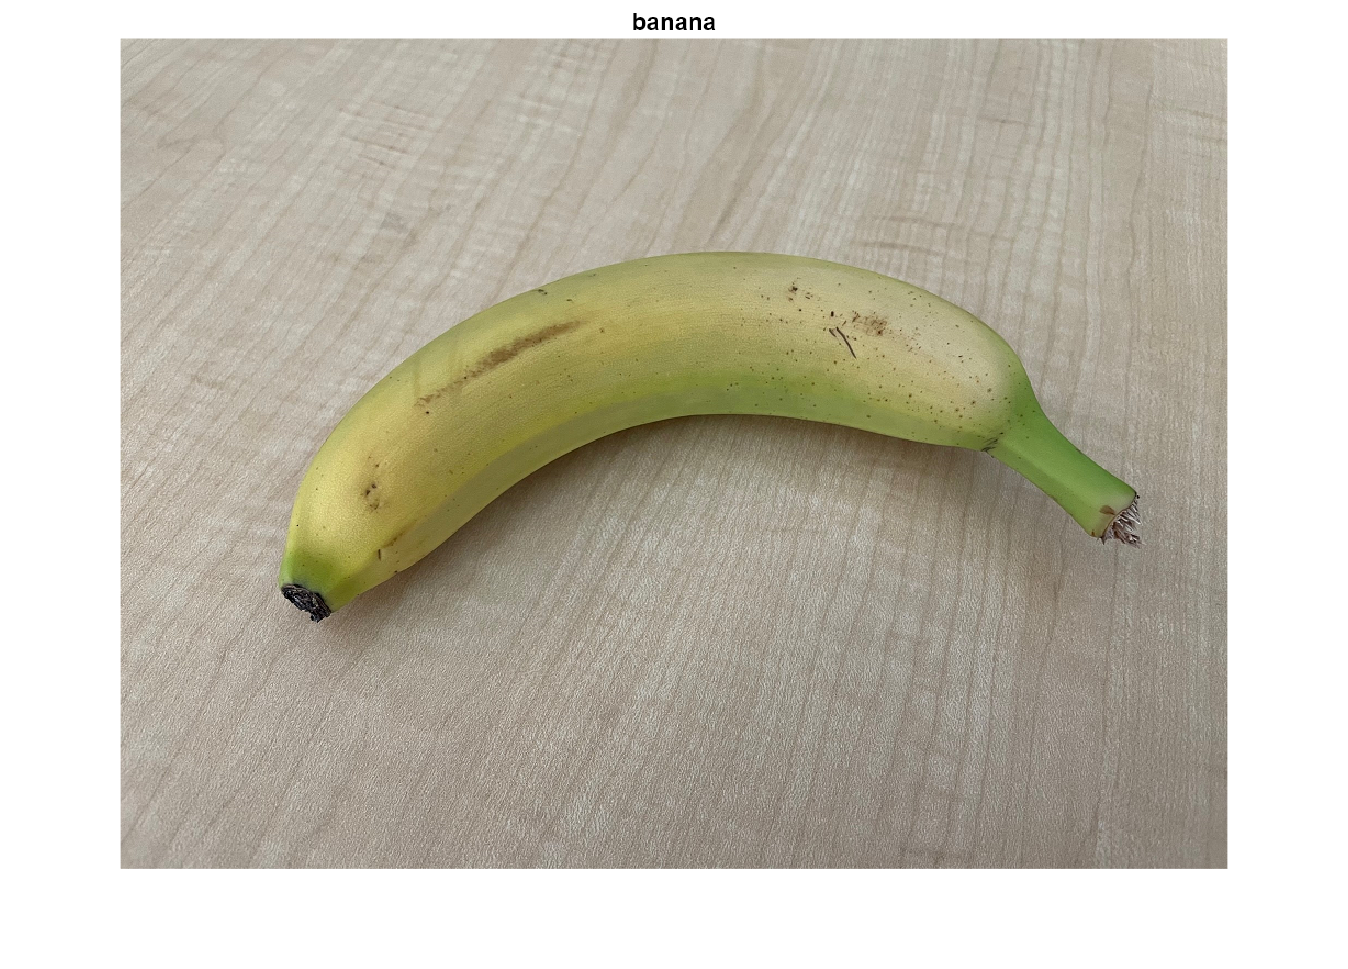


figure
imshow(imgOriginal);
title(string(label2));

*© 2022, The MathWorks, Inc.*